# Atividade 13_05

Otávio Baziewicz Filho - 1942808

clc; clear; close all;

## Análise das imagens térmicas

Elabore um script para realizar a seguinte análise: obter os valores mínimo e máximo de temperatura do sujeito (corpo da pessoa), considerando todas as 20 imagens do conjunto. Note que, para isso, será necessário segmentar o sujeito (separar o corpo da pessoa do fundo da imagem). Para as temperaturas mínima e máxima, seu script deve mostrar a imagem na qual ocorreu a temperatura, o valor da temperatura, e algum tipo de identificação (marcação na imagem) do pixel no qual ocorreu essa temperatura.

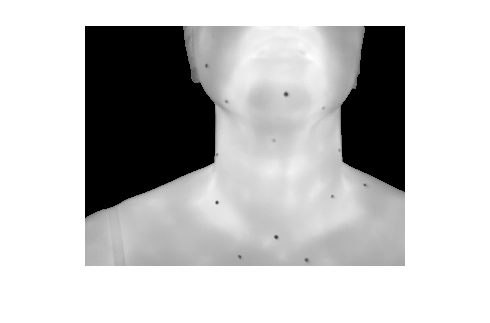

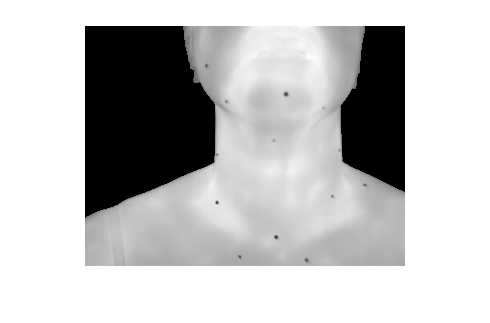

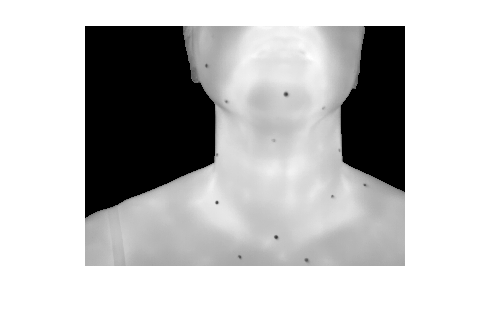

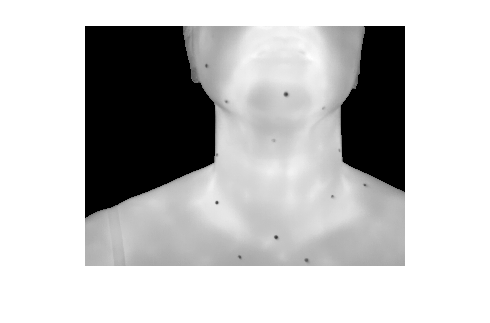

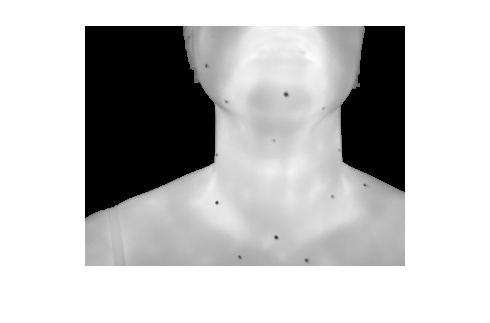

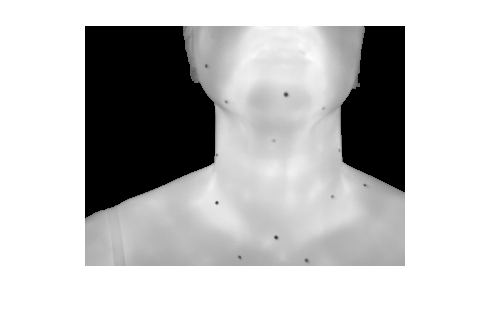

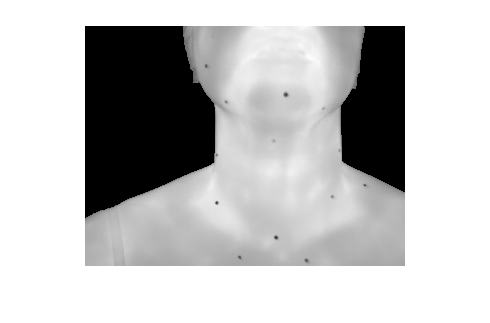

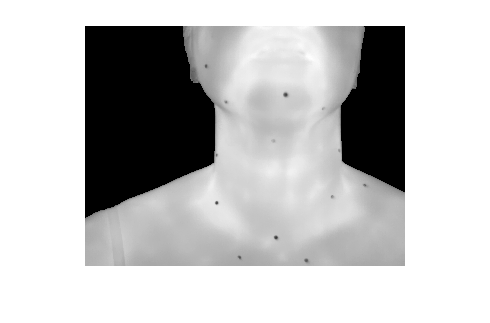

frames = readmatrix("frames.csv");

cm = colormap(jet(256));

for i = 1:20
    imgTmp = frames((i-1)*240+1:i*240,:);
    imgTmp = flip(imgTmp);

    img = mat2gray(imgTmp);
    img = uint8(img.*255);

    th = graythresh(img);
    bw = imbinarize(img, th);
    bw = imclose(bw, strel("square", 7));
    bw = imopen(bw, strel("square", 4));
    bw = imfill(bw, "holes");

    imgSeg = uint8(double(img) .* repmat(bw, [1 1 1]));
    imgTmpSeg = imgTmp .* repmat(bw, [1 1 1]);

    [maxI,maxJ] = find(imgTmpSeg == max(imgTmpSeg(:)), 1);
    [minI,minJ] = find(imgTmpSeg == min(imgTmpSeg), 1);

    %% INCOMPLETO :<
    
    figure, imshow(imgSeg)


end